# Week 1 - Matlab fourier

## Auteur: Perijn Huijser

## Datum: 10-09-2025

## Opdracht 1)

### Initialisatie

close all
clear

syms t n

### A) Bepaal de periode tijd

% Zet het getal '4' om naar een symbolische object indien Matlab het nodig
% vind
T = sym(4);

### B) Bepaal de hoeksnelheid

% Verander het getal 'pi' naar een rationeel symbolische getal. Dit is
% beter en vertrouwbaarder voor symbolische formules, bij bijvoorbeeld
% het simplificeren van formules
omega = 2 * sym(pi) / T

$$omega = \frac{\pi }{2}$$

### C) Bepaal of er sprake is van symmetrie

Nee, er is geen sprake van symmetrie

### D) Wat zijn de consequenties van gevonden symmetrie

de $a_n$ termen vervallen

### E) Stel de functieomschrijving in

% Hier gebruik ik de modules functie zodat de plot continu is.
% Maar ik zou ook 1 periode kunnen plotten met de piecewise functie
f = piecewise((mod(t,T) > 0) & (mod(t,T) < T), 2*mod(t,T));

% Piecewise versie voor 1 periode. Deze functie wordt uiteindelijk gebruikt
% voor de coefficienten te berekenen
fp = piecewise((t > 0) & (t < T), 2*t);

### F) Teken de bij 'E' bepaalde functie

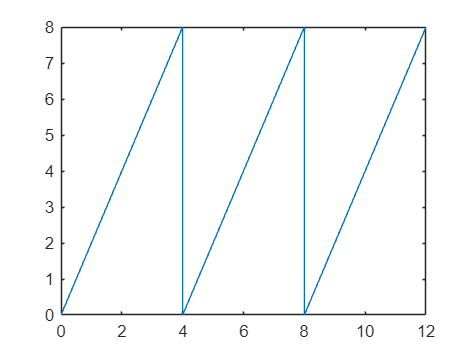

figure;
fplot(f, [0,12])

### G & H) Bepaal de Fourier coefficienten $a_0 ,a_n \;\mathrm{en}\;b_n$

#### Formules: $a_n =\frac{2}{T}*\int_0^T f\left(t\right)*\cos \left(n\omega t\right)\mathrm{dt}\;$

                
$$b_n =\frac{2}{T}*\int_T^0 f\left(t\right)*\sin \left(n\omega t\right)\mathrm{dt}$$


                
$$a_0 =\frac{2}{T}*\int_T^0 f\left(t\right)\mathrm{dt}$$


#### Uitvoering:

Header("Custom functie")

_____________________________________________________________
Custom functie
_____________________________________________________________



% Als allereerste heb gebruik ik hier mijn eigen functie voor de
% coefficienten te bereken waarbij:
%   anf - Dit is de an term gewrapped in een functie handler
%   bnf - Dit is de bn term gewrapped in een functie handler
%   a0  - Dit is de a0 term
%   an  - Dit is de 'rauwe' versimpelde versie van de an term
%   bn  - Dit is de 'rauwe' versimpelde versie van de bn term
if exist("FourierCoefficients","file")
    [anf, bnf, a0, an, bn] = FourierCoefficients(fp, t, T);
end

fprintf("Versimpelde versie an"); an

Versimpelde versie an

$$an = 0$$

fprintf("Versimpelde versie bn"); bn

Versimpelde versie bn

$$bn = -\frac{8}{n\,\pi }$$

fprintf("a0 term"); a0

a0 term

$$a0 = 8$$


% De formules die gebruikt worden in de custom functie
Header("Formules")

_____________________________________________________________
Formules
_____________________________________________________________



% Vertel Matlab dat symbolische variable 'n' een geheel getal is
assume(n, 'integer');

an = 2/T * int(fp * cos(n * omega * t), t, [0, T]);
an = simplify(an)

$$an = 0$$


bn = 2/T * int(fp * sin(n * omega * t), t, [0, T]);
bn = simplify(bn)

$$bn = -\frac{8}{n\,\pi }$$


a0 = (2/T) * int(fp, t, [0, T]);
a0 = simplify(a0)

$$a0 = 8$$


% Wrap de an en bn termen in een functie handle. Dit maakt later gebruik
% makkelijker en overzichtelijker. Dit is precies hetzelfde wat de custom
% 'FourierCoefficients' functie terug geeft
anf = @(i) subs(an, n, i);
bnf = @(i) subs(bn, n, i);

% Verwijder de assumptie
assume(n, 'clear')

### I) Bepaalde de eerste 7 termen van de Fouriercoefficienten

% Doordat de termen 'gewrapped' zijn, zijn ze makkelijker bruikbaar.
Header("Eerste 7 termen")

_____________________________________________________________
Eerste 7 termen
_____________________________________________________________



an_list = anf(1:7)

$$an\_list = \left(\begin{array}{ccccccc} 0 & 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

bn_list = bnf(1:7)

$$bn\_list = \left(\begin{array}{ccccccc} -\frac{8}{\pi } & -\frac{4}{\pi } & -\frac{8}{3\,\pi } & -\frac{2}{\pi } & -\frac{8}{5\,\pi } & -\frac{4}{3\,\pi } & -\frac{8}{7\,\pi } \end{array}\right)$$

### J) Schrijf de eeste 7 termen van de Fourierreeks

#### Formules: 

                    
$$f\left(t\right)=\frac{1}{2}a_0 +\sum_{n=1}^n a_n *\cos \left(n\omega t\right)+b_{n\;} *\sin \left(n\omega t\right)$$


Header("Fourierreeks eerste 7 termen")

_____________________________________________________________
Fourierreeks eerste 7 termen
_____________________________________________________________



% Bereken de Fourierreeks van de eerste 7 termen. Hiervoor wordt symsum
% gebruikt, wat dus symbolisch sommator function is.
syms k
terms = a0/2 + symsum(anf(k) * cos(k*omega*t) + bnf(k) * sin(k*omega*t), k, 1, 7)

$$terms = 4-\frac{2\,\sin\left(2\,\pi \,t\right)}{\pi }-\frac{8\,\sin\left(\frac{\pi \,t}{2}\right)}{\pi }-\frac{4\,\sin\left(3\,\pi \,t\right)}{3\,\pi }-\frac{8\,\sin\left(\frac{3\,\pi \,t}{2}\right)}{3\,\pi }-\frac{8\,\sin\left(\frac{5\,\pi \,t}{2}\right)}{5\,\pi }-\frac{8\,\sin\left(\frac{7\,\pi \,t}{2}\right)}{7\,\pi }-\frac{4\,\sin\left(\pi \,t\right)}{\pi }$$


% Alternatief heb ik hier ook een custom functie voor gemaakt om dit automatisch
% voor mij te doen

if exist("FourierSerie","file")
    terms = FourierSerie(fp, t, T, 7);
end

### K) Teken de Fourierreeks van f(t) die bepaald is bij vraag 'J'

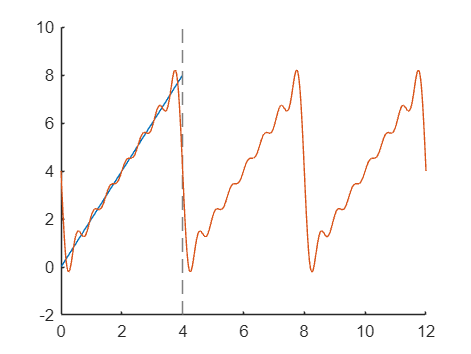

figure;
hold on
fplot(fp, [0, 12]);
fplot(terms, [0, 12]);

### L) Vergelijk de beide lijnen in de grafiek welke getekent zijn bij vraag 'K'

Ze lijken wel grotendeels op elkaarr, maar het is overduidelijk dat de Fourierreeks niet perfect is

### M) Bepaal de THD voor respectievelijk 7 en 100 termen

#### Formules:

                    
$$C_n =\sqrt{{a_n }^2 +{b_n }^2 }$$


                    
$$\mathrm{THD}=\frac{\sqrt{{C_2 }^2 +{C_3 }^2 +{\ldotp \ldotp \ldotp +\;C_{\infty } }^2 }}{\left|C_1 \right|}$$


#### Uitvoering:

% Functie voor de Cn termen. Ook deze formule wordt 'gewrapped'. Dit maakt
% het makkelijker om voor meerdere termen, dezelfde variable te gebruiken
Cn = @(n) sqrt(anf(n)^2 + bnf(n)^2);

% Wrap ook de THD formule in een functie handle, aangezien deze formule bestaat uit 
% n = 2 tot n = ∞. Dus is het handiger om ook deze variable voor meerdere termen
% te gebruiken
THD = @(j) sqrt(symsum(Cn(k)^2, k, 2, j)) / abs(Cn(1));

% Bereken de total harmonic distortion bij de verschillende termen
THD_7 = double(THD(7))

THD_7 = 0.7154

THD_100 = double(THD(100))

THD_100 = 0.7969

### N) Maak een lijnenspectrum van $a_n \;\mathrm{en}\;b_n$voor de eerste 10 coefficienten

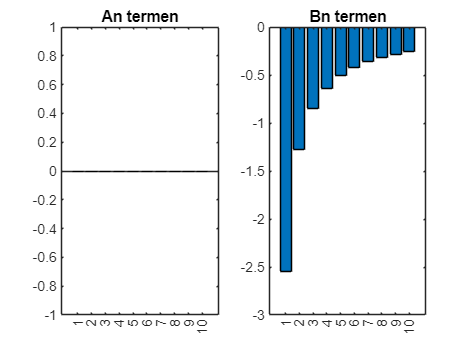

figure;
subplot(1,2, 1);
bar(anf(1:10));
title("An termen")

subplot(1,2, 2);
bar(bnf(1:10));
title("Bn termen")